# PRÁCTICA 9: Descripción y Representación (1ª parte)

## PROPIEDADES DE UNA REGIÓN

- ‘all’, 'Area’, 'EulerNumber', 'Orientation', 'BoundingBox', 'Extent', 'Perimeter', 'Centroid', 'Extrema', 'ConvexArea', 'FilledArea', 'ConvexHull', 'FilledImage', 'ConvexImage', ' Image', 'Eccentricity', 'MajorAxisLength', 'EquivDiameter', 'MinorAxisLength'

NOTA: Si la imagen contiene más de una región binaria (conectada), el vector de salida tendrá una estructura para cada una de las regiones.

#### EJEMPLO

#### EJERCICIO 1

Cargue las imágenes “Classification\Parts00.png” y “Gears\Parts 01.jpg” (im1 e im2) y obtenga la binarización de ambas mediante umbralización óptima (imbinarize) (im1b e im2b), de tal manera que los objetos aparezcan en blanco sobre fondo negro (calcule la negada en caso necesario). Muestre en una figura las cuatro imágenes, subplot(2,2,…) .

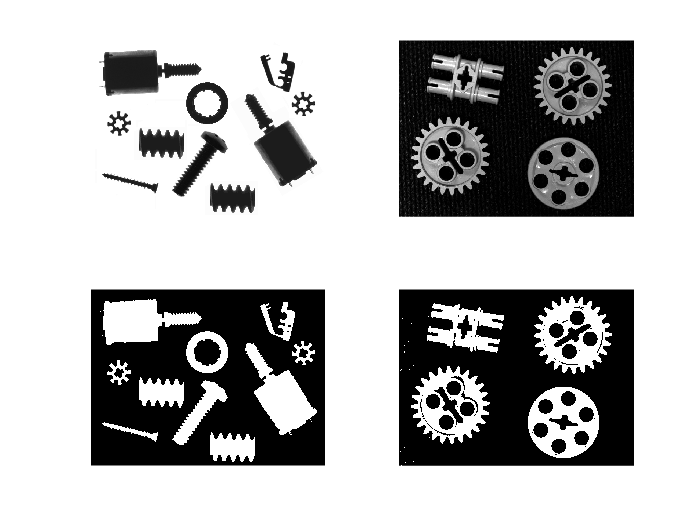

im1 = imread("Parts00.png");
im2 = imread("Parts 01.jpg");
im1b = imbinarize(im1);
im2b = imbinarize(im2);
figure
subplot(221); imshow(im1);
subplot(222); imshow(im2);
subplot(223); imshow(1-im1b);
subplot(224); imshow(im2b);

#### EJERCICIO 2

Segmente uno de los objetos de la imagen im1 (o im2) mediante crecimiento de regiones (vercre_isa, umbral 90) (ob) y obtenga todas sus propiedades (regionprops). Compruebe su área, perímetro, área convexa y excentricidad.

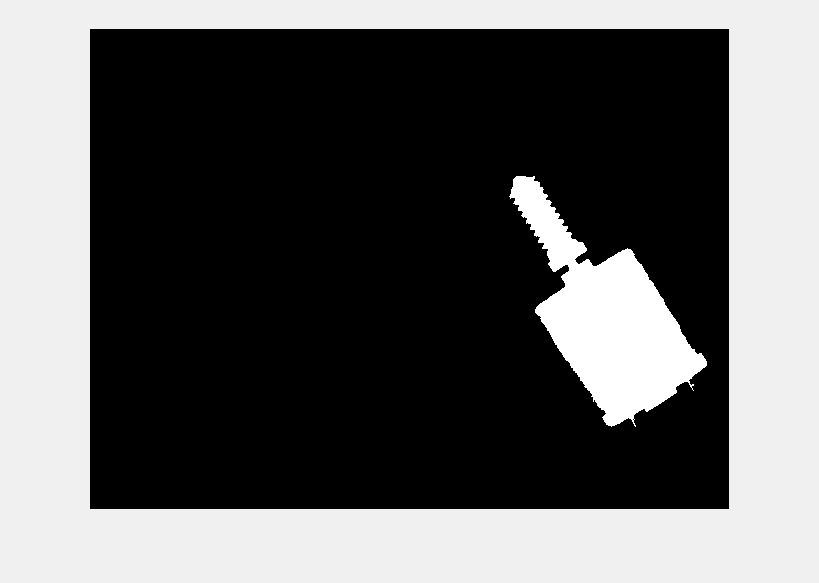

res = vercre_isa(im1b, 0.90); %Segmente uno de los objetos de la imagen im1 (o im2) mediante crecimiento de regiones (vercre_isa, umbral 90)

pro = regionprops (res,'all'); % (ob) y obtenga todas sus propiedades (regionprops). 
pro.Area % Compruebe su área,

ans = 20078

pro.Perimeter  % perímetro, 

ans = 916.5750

pro.ConvexArea % área convexa y 

ans = 26018

pro.Eccentricity % excentricidad.

ans = 0.8856

#### EJERCICIO 3

Muestre en una figura una imagen que contenga el objeto segmentado del ejercicio anterior en rojo sobre la imagen original y un asterisco marcando su centroide (‘Centroid’). 

En otra figura represente la región segmentada (‘Image’), el cerco convexo de la región (‘ConvexImage’), la región rellena (‘FilledImage’) y diferencia convexa (‘ConvexImage’ – ‘FilledImage’). suplot (2,2,…)

NOTA: Para mostrar la región en rojo (ob) sobre la imagen puede emplear el código:

>> imshow (double(im).*not (ob) + ob * 256 , [ gray (255); 1 0 0]);

suponiendo que ‘im’ contiene la imagen original y ‘ob’ el objeto segmentado binario.

#### EJERCICIO 4

. Repita los ejercicios 2 y 3 con varios objetos.

## SIGNATURA DE UNA REGION

<signatura> = signatura_isa (<objeto_binario>);

Devuelve una matriz de nx2, donde la primera columna es el ángulo en radianes y la segunda la distancia euclídea al centroide.

#### EJERCICIO 5

. Estudie el algoritmo signatura_isa y utilícelo para obtener la signatura de todos los objetos de la imagen im1b. Para cada uno de los objetos segmentados represente en una figura la región binaria rellena (FilledImage), el cerco convexo (ConvexImage) y la signatura de cada una de ellas. (subplot(2,2,…)).

NOTA 1: Para representar la signatura hay que emplear el comando plot (ángulos, distancias),

NOTA 2: Obtenga las propiedades de todas las regiones conectadas de forma simultánea con regionprops y emplee un bucle for para procesar todos los objetos, descartando aquellos cuya área sea inferior a 20.

>> pro = regionprops (imb1,’ FilledImage’, ’ConvexImage’, ’Area’);

>> for k = 1: numel(pro)

>> ……

## ESQUELETO DE UNA REGION (ZANG Y SUEN)

<imagen_esqueleto> = veradel_isa (<objeto_binario>);

EJERCICIOS:

#### EJERCICIO 6

. Estudie el algoritmo veradel_isa y utilícelo para obtener el esqueleto de un objeto de la imagen im2, previamente segmentados (vercre_isa, umbral 90) y con sus huecos rellenos (‘FilledImage’). Repita el ejercicio anterior para cada tipo de objeto presente en la imagen im2 (polea, engranaje y eje)

#### EJERCICIO 7

. Aplique un adelgazamiento a la imagen imb1 (todos los objetos en blanco sobre fondo en negro) y muestre en una figura la imagen original y los esqueletos de los objetos superpuestos en verde.

>> imshow (double(im1).*not(esqueleto) + esqueleto*256, [ gray(255); 0 1 0]) ;

## OPERADORES MORFOLÓGICOS

‘dilate’

‘erode’

‘open’

bwmorph (<imagen binaria>,’<operador>’, <iteraciones>); ‘close’

‘skel’

‘thin’

‘endpoints’

EJERCICIOS:

#### EJERCICIO 8

. Repita el ejercicio 7 empleando adelgazamiento morfológico

>> esqueleto = bwmorph (<imagen binaria>,’thin’,inf );

#### EJERCICIO 9

. Aplique la siguiente secuencia de operadores morfológicos para la mejora de la imagen im2b de tal forma que sólo queden las piezas con sus huecos principales (im3b). Muestre en una figura la imagen binaria original y las tres imágenes intermedias, subplot (2,2,…)

open  dilate (5)  erode (5)

#### EJERCICIO 10

. Realice y muestre el adelgazamiento morfológico de la imagen im3b. ¿Se mantiene en este resultado inalterado en número de Euler de cada objeto de la imagen im3b?

#### EJERCICIO 11

. Cargue las imágenes de la carpeta “ .\Lcd\ ..” y aplíqueles la siguiente secuencia para la obtención del esqueleto de los dígitos para su posterior procesamiento.

a) Igualación de histograma  histeq ()

b) Binarización con umbral 0.25  im2bw ()

c) Negada  not ()

d) Una erosión

e) Cuatro dilataciones  bwmorph ()

f) Adelgazamiento hasta obtener

el esqueleto.

#### EJERCICIO 12

. Muestre en una figura la imagen original y el resultado final, para todas las imágenes. ¿Cómo descartaría aquellos pixeles que no forman parte de los dígitos?